clf;
clear;

Baboon = imread("../materials/Baboon.tif");
size(Baboon)

ans =    512   512


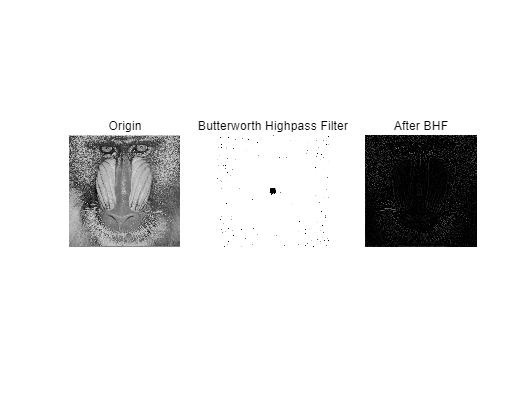


FFT_Baboon = fftshift(fft2(im2double(im2gray(Baboon))));
BHF_Filter = my_BHF(FFT_Baboon,4); % 4th
BHF_Baboon = im2uint8(real(ifft2(ifftshift(BHF_Filter))));

subplot(1,3,1);
imshow(Baboon);title('Origin');
subplot(1,3,2);
imshow(log(abs(BHF_Filter)));title('Butterworth Highpass Filter');
subplot(1,3,3);
imshow(BHF_Baboon);title('After BHF');

function out = my_BHF(image, set) % Butterworth Highpass Filter
    [M,N] = size(image);
    m = ceil(M/2);
    n = ceil(N/2);
    out = [M,N];

    D0 = 30;
    for  i=1:M
        for j=1:N
            d=sqrt((i-m)^2+(j-n)^2);            
            if (d==0)               
                h=0; 
            else 
                h=1/(1+0.414*(D0/d)^(2*set));    
            end 
            out(i,j)=h*image(i,j);
        end 
    end
end